### **Renombrar variables**

VariableNames = {...
    'SpMax_L', 'J_Dz(e)', 'nHM', 'F01[N-N]', 'F04[C-N]', 'NssssC', ...
    'nCb-', 'C%', 'nCp', 'nO', 'F03[C-N]', 'SdssC', 'HyWi_B(m)', 'LOC', ...
    'SM6_L', 'F03[C-O]', 'Me', 'Mi', 'nN-N', 'nArNO2', 'nCRX3', ...
    'SpPosA_B(p)', 'nCIR', 'B01[C-Br]', 'B03[C-Cl]', 'N-073', 'SpMax_A', ...
    'Psi_i_1d', 'B04[C-Br]', 'SdO', 'TI2_L', 'nCrt', 'C-026', 'F02[C-N]', ...
    'nHDon', 'SpMax_B(m)', 'Psi_i_A', 'nN', 'SM6_B(m)', 'nArCOOR', 'nX', ...
    'experimental_class'...
};

biodeg_copy.Properties.VariableNames = VariableNames;

rng(385567); % Semilla para reproducibilidad

% definir variables para OHE
outputs = biodeg.experimental_class;
classes = cellstr(unique(outputs)); % {'NRB', 'RB'}

## Entrenamiento de Red Neuronal

% =======================================================
% ==================== CONFIGURACIÓN ====================
% =======================================================

% Variables predictoras y etiquetas
X = biodeg{:, 1:41};
Y = biodeg.experimental_class;
onehotQSAR = onehotencode(categorical(Y), 2, 'ClassNames', classes); % ONE HOT ENCODING DE LABELS
T = array2table(onehotQSAR, 'VariableNames', {'NRB_OHE','RB_OHE'});

variablesContinuas = [1,2,8,12,13,14,15,17,18,22,27,28,30,31,36,37,39];
NumClases = length(classes);

% Definir configuraciones de la red neuronal
numNeuronas = [5, 10, 15];  % número de neuronas en la capa oculta
algoritmosEntrenamiento = {'trainscg', 'trainlm'};  % algoritmos de entrenamiento (primer orden: gradiente conjugado escalado, 
                                                    %                              segundo orden: Levenberg-Marquardt)
number_reps = 3;  % número de repeticiones

% Generar combinaciones
[NEUR, ALG] = ndgrid(numNeuronas, 1:length(algoritmosEntrenamiento));
combinaciones = [NEUR(:), ALG(:)];
numCombinaciones = size(combinaciones, 1);


% Inicializar almacenamiento por fold
metricsFoldsNN = struct();
metricsFoldsNN.Accuracy = zeros(10, numCombinaciones, number_reps);
metricsFoldsNN.Recall = zeros(10, numCombinaciones, number_reps);
metricsFoldsNN.Precision = zeros(10, numCombinaciones, number_reps);
metricsFoldsNN.Specificity = zeros(10, numCombinaciones, number_reps);
metricsFoldsNN.F1Score = zeros(10, numCombinaciones, number_reps);

% ====================================================================
% ==================== ENTRENAMIENTO Y EVALUACIÓN ====================
% ====================================================================
for modelIdx = 1:numCombinaciones
    nHidden = combinaciones(modelIdx, 1);
    algIdx = combinaciones(modelIdx, 2);
    algoritmo = algoritmosEntrenamiento{algIdx};
    
    fprintf('\n=== MODELO %d de %d ===\n', modelIdx, numCombinaciones);
    fprintf('Configuración: %d neuronas ocultas - Algoritmo: %s\n', nHidden, algoritmo);

    for rep = 1:number_reps
        fprintf('   > Repetición %d de %d\n', rep, number_reps);

        Y_true_all = strings(size(Y));
        Y_pred_all = strings(size(Y));
        
        cv = cvpartition(Y, 'KFold', 10, 'Stratify', true);  

        for fold = 1:cv.NumTestSets
            trainIdx = training(cv, fold);
            testIdx = test(cv, fold);

            X_train = X(trainIdx, :);
            T_train = T{trainIdx, :};
            X_test = X(testIdx, :);
            Y_test = Y(testIdx);

            % Normalizar
            mn = mean(X_train(:, variablesContinuas));
            sd = std(X_train(:, variablesContinuas));
            X_train(:, variablesContinuas) = (X_train(:, variablesContinuas) - mn) ./ sd;
            X_test(:, variablesContinuas) = (X_test(:, variablesContinuas) - mn) ./ sd;

            % Crear red
            net = patternnet(nHidden);
            net.trainFcn = algoritmo;

            net.divideParam.trainRatio = 0.8;
            net.divideParam.valRatio = 0.2;
            net.divideParam.testRatio = 0.0;

            net.trainParam.showWindow = 0;
            %net.trainParam.epochs = 200;

            % Entrenar
            net = train(net, X_train', T_train');

            % Predecir
            outTest = net(X_test');
            pred = onehotdecode(outTest', classes, 2);

            % Guardar predicciones
            Y_true_all(testIdx) = string(Y_test);
            Y_pred_all(testIdx) = string(pred);

            % Calcular matriz de confusión por fold
            CM = confusionmat(categorical(Y_test), categorical(pred), 'Order', classes);
            
            % IMPORTANTE: aquí indicamos que la clase positiva es la segunda (RB)
            positiveClassIdx = 2; 

            [recall, specificity, precision, ~, accuracy, f1score] = performanceIndexes(CM, positiveClassIdx);

            % Guardar métricas fold a fold
            metricsFoldsNN.Accuracy(fold, modelIdx, rep) = accuracy;
            metricsFoldsNN.Recall(fold, modelIdx, rep) = recall;
            metricsFoldsNN.Precision(fold, modelIdx, rep) = precision;
            metricsFoldsNN.Specificity(fold, modelIdx, rep) = specificity;
            metricsFoldsNN.F1Score(fold, modelIdx, rep) = f1score;
        end
    end
end


=== MODELO 1 de 6 ===


Configuración: 5 neuronas ocultas - Algoritmo: trainscg


   > Repetición 1 de 3
   > Repetición 2 de 3
   > Repetición 3 de 3



=== MODELO 2 de 6 ===


Configuración: 10 neuronas ocultas - Algoritmo: trainscg


   > Repetición 1 de 3
   > Repetición 2 de 3
   > Repetición 3 de 3



=== MODELO 3 de 6 ===


Configuración: 15 neuronas ocultas - Algoritmo: trainscg


   > Repetición 1 de 3
   > Repetición 2 de 3
   > Repetición 3 de 3



=== MODELO 4 de 6 ===


Configuración: 5 neuronas ocultas - Algoritmo: trainlm


   > Repetición 1 de 3


   > Repetición 2 de 3


   > Repetición 3 de 3



=== MODELO 5 de 6 ===


Configuración: 10 neuronas ocultas - Algoritmo: trainlm


   > Repetición 1 de 3


   > Repetición 2 de 3


   > Repetición 3 de 3



=== MODELO 6 de 6 ===


Configuración: 15 neuronas ocultas - Algoritmo: trainlm


   > Repetición 1 de 3


   > Repetición 2 de 3


   > Repetición 3 de 3


% Guardar todos los modelos, métricas y configuraciones
save('NN_QSAR_ModelosCompletos.mat', ...
    'nnModels', 'metricsFoldsNN', 'combinaciones', 'algoritmosEntrenamiento', ...
    'Mean_ACC', 'Std_ACC', 'Mean_Recall', 'Std_Recall', ...
    'Mean_Precision', 'Std_Precision', 'Mean_Specificity', 'Std_Specificity', ...
    'Mean_F1', 'Std_F1', 'classes');

% Cargar todos los modelos y métricas previamente guardados
%load('NN_QSAR_ModelosCompletos.mat');

function mostrarResumenNN(combinaciones, algoritmosEntrenamiento, ...
    Mean_ACC, Std_ACC, ...
    Mean_Recall, Std_Recall, ...
    Mean_Precision, Std_Precision, ...
    Mean_Specificity, Std_Specificity, ...
    Mean_F1, Std_F1)

    numCombinaciones = size(combinaciones, 1);

    modelo = strings(numCombinaciones, 1);
    Neurons = zeros(numCombinaciones, 1);
    algoritmo = strings(numCombinaciones, 1);

    Accuracy = zeros(numCombinaciones, 1);
    Accuracy_std = strings(numCombinaciones, 1);
    Recall = zeros(numCombinaciones, 1);
    Recall_std = strings(numCombinaciones, 1);
    Precision = zeros(numCombinaciones, 1);
    Precision_std = strings(numCombinaciones, 1);
    Specificity = zeros(numCombinaciones, 1);
    Specificity_std = strings(numCombinaciones, 1);
    F1 = zeros(numCombinaciones, 1);
    F1_std = strings(numCombinaciones, 1);

    for i = 1:numCombinaciones
        modelo(i) = sprintf("NN %d", i);
        Neurons(i) = combinaciones(i, 1);
        algoritmo(i) = algoritmosEntrenamiento{combinaciones(i, 2)};

        Accuracy(i) = Mean_ACC(i);
        Accuracy_std(i) = compose('%.4f', Std_ACC(i));
        Recall(i) = Mean_Recall(i);
        Recall_std(i) = compose('%.4f', Std_Recall(i));
        Precision(i) = Mean_Precision(i);
        Precision_std(i) = compose('%.4f', Std_Precision(i));
        Specificity(i) = Mean_Specificity(i);
        Specificity_std(i) = compose('%.4f', Std_Specificity(i));
        F1(i) = Mean_F1(i);
        F1_std(i) = compose('%.4f', Std_F1(i));
    end

    tabla = table(modelo, Neurons, algoritmo, ...
        Accuracy, Accuracy_std, ...
        Recall, Recall_std, ...
        Precision, Precision_std, ...
        Specificity, Specificity_std, ...
        F1, F1_std);

    disp(tabla);
end

% Inicializar estructuras por métrica
Mean_ACC = squeeze(mean(metricsFoldsNN.Accuracy, 1));
Std_ACC  = squeeze(std(metricsFoldsNN.Accuracy, 0, 1));
Mean_Recall = squeeze(mean(metricsFoldsNN.Recall, 1));
Std_Recall  = squeeze(std(metricsFoldsNN.Recall, 0, 1));
Mean_Precision = squeeze(mean(metricsFoldsNN.Precision, 1));
Std_Precision  = squeeze(std(metricsFoldsNN.Precision, 0, 1));
Mean_Specificity = squeeze(mean(metricsFoldsNN.Specificity, 1));
Std_Specificity  = squeeze(std(metricsFoldsNN.Specificity, 0, 1));
Mean_F1 = squeeze(mean(metricsFoldsNN.F1Score, 1));
Std_F1  = squeeze(std(metricsFoldsNN.F1Score, 0, 1));

% Promedio sobre repeticiones
Mean_ACC = mean(Mean_ACC, 2);
Std_ACC  = mean(Std_ACC, 2);
Mean_Recall = mean(Mean_Recall, 2);
Std_Recall  = mean(Std_Recall, 2);
Mean_Precision = mean(Mean_Precision, 2);
Std_Precision  = mean(Std_Precision, 2);
Mean_Specificity = mean(Mean_Specificity, 2);
Std_Specificity  = mean(Std_Specificity, 2);
Mean_F1 = mean(Mean_F1, 2);
Std_F1  = mean(Std_F1, 2);



mostrarResumenNN(combinaciones, algoritmosEntrenamiento, ...
    Mean_ACC, Std_ACC, ...
    Mean_Recall, Std_Recall, ...
    Mean_Precision, Std_Precision, ...
    Mean_Specificity, Std_Specificity, ...
    Mean_F1, Std_F1);

    modelo    Neurons    algoritmo     Accuracy    Accuracy_std    Recall     Recall_std    Precision    Precision_std    Specificity    Specificity_std      F1        F1_std 
    ______    _______    __________    ________    ____________    _______    __________    _________    _____________    ___________    _______________    _______    ________

    "NN 1"       5       "trainscg"    0.84142       "0.0389"      0.75643     "0.0730"      0.77473       "0.0703"         0.88464         "0.0470"        0.76283    "0.0567"
    "NN 2"      10       "tra

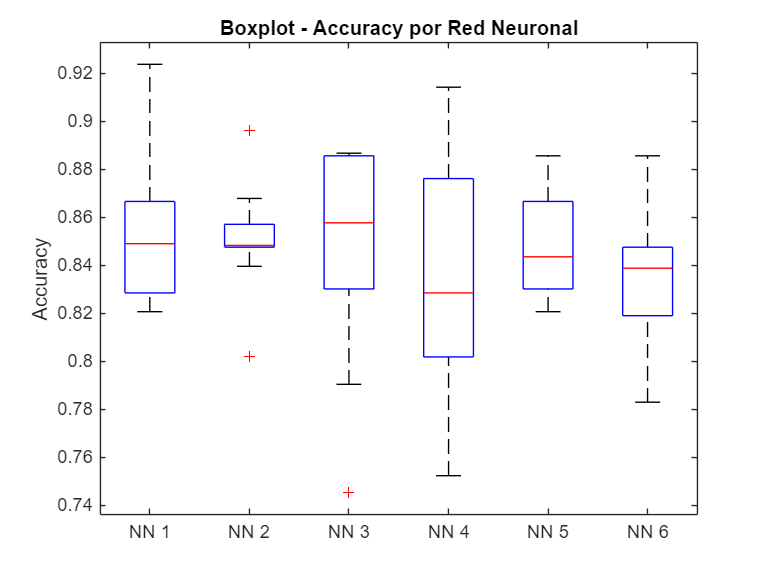

rep = 1;  % Repetición que quieras visualizar
numModelos = size(metricsFoldsNN.Accuracy, 2);

% Obtener las accuracies por fold de cada modelo
accMatrix = squeeze(metricsFoldsNN.Accuracy(:, :, rep));  % (folds × modelos)
f1Matrix  = squeeze(metricsFoldsNN.F1Score(:, :, rep));   % (folds × modelos)

% Etiquetas para los modelos
labels = strings(1, numModelos);
for i = 1:numModelos
    labels(i) = sprintf('NN %d', i);
end

% Boxplot de Accuracy
figure;
boxplot(accMatrix, 'Labels', labels);
ylabel('Accuracy');
title('Boxplot - Accuracy por Red Neuronal');

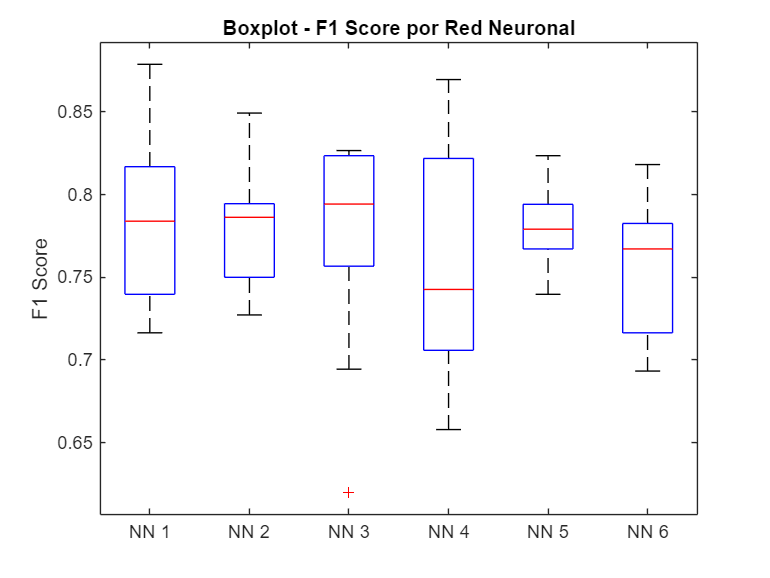



% Boxplot de F1Score
figure;
boxplot(f1Matrix, 'Labels', labels);
ylabel('F1 Score');
title('Boxplot - F1 Score por Red Neuronal');

% === COMPARACIÓN ENTRE REDES NEURONALES POR MÉTRICA ===

rep = 1;  % Seleccionamos una repetición
numCombinaciones = size(metricsFoldsNN.Accuracy, 2);
numFolds = size(metricsFoldsNN.Accuracy, 1);

metricNames = {'Accuracy', 'Recall', 'Precision', 'Specificity', 'F1Score'};

for m = 1:numel(metricNames)
    metricName = metricNames{m};
    metric_todos = [];
    grupos = [];
    
    % Extraer valores reales de los folds
    for modelIdx = 1:numCombinaciones
        metric_values = metricsFoldsNN.(metricName)(:, modelIdx, rep);
        
        metric_todos = [metric_todos; metric_values];
        grupos = [grupos; repmat(modelIdx, numFolds, 1)];
    end
    
    % Kruskal-Wallis
    [p_kw, tabla_kw, stats_kw] = kruskalwallis(metric_todos, grupos, 'off');
    fprintf("\nKruskal-Wallis para %s (rep %d): p = %.4f\n", metricName, rep, p_kw);
    
    if p_kw < 0.05
        fprintf("Diferencias significativas detectadas en %s. Realizando comparaciones múltiples:\n", metricName);
        figure;
        title(sprintf('Comparaciones múltiples para %s', metricName));
        cNN = multcompare(stats_kw, 'CType', 'bonferroni');
    else
        fprintf("No se detectaron diferencias significativas en %s.\n", metricName);
    end
end


Kruskal-Wallis para Accuracy (rep 1): p = 0.5113


No se detectaron diferencias significativas en Accuracy.



Kruskal-Wallis para Recall (rep 1): p = 0.6550


No se detectaron diferencias significativas en Recall.



Kruskal-Wallis para Precision (rep 1): p = 0.8948


No se detectaron diferencias significativas en Precision.



Kruskal-Wallis para Specificity (rep 1): p = 0.9842


No se detectaron diferencias significativas en Specificity.



Kruskal-Wallis para F1Score (rep 1): p = 0.5042


No se detectaron diferencias significativas en F1Score.


El test global de Kruskal-Wallis no indicó diferencias significativas en Accuracy y F1Score entre los modelos evaluados. Por tanto, optamos por seleccionar como modelo final el más sencillo, priorizando la parsimonia y evitando sobreajuste innecesario. En este caso, el modelo elegido fue NN1 (5 neuronas ocultas, algoritmo trainscg), que mostró un desempeño competitivo frente a configuraciones más complejas.

% === GUARDAR MEJOR MODELO SIMPLE NN EN DISCO ===

% Encontrar el índice del modelo más sencillo (5 neuronas, trainscg)
idx_sencillo = find(combinaciones(:,1) == 5 & combinaciones(:,2) == 1);

mejorNN = nnModels{1, idx_sencillo, rep};  % rep = 1

modeloFinal.red = mejorNN;
modeloFinal.mediaTrain = mn;     % media usada para normalizar durante el entrenamiento
modeloFinal.stdTrain = sd;       % desviación típica
modeloFinal.clases = classes;

% Guardarlo en disco
save('modeloFinal_NN_QSAR.mat', 'modeloFinal');


Test de Kruskal-Wallis para Accuracy


P-valor: 0.0264


Se encontraron diferencias significativas entre los modelos. Realizando comparaciones múltiples...


Note: Intervals can be used for testing but are not simultaneous confidence intervals.


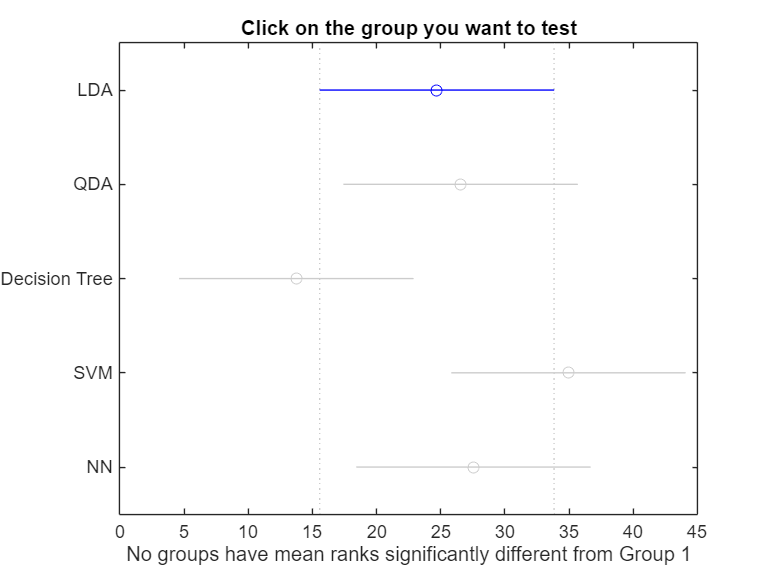

    Grupo1    Grupo2    Lower_CI     Diff     Upper_CI     PValue 
    ______    ______    ________    ______    ________    ________

      1         2       -20.117      -1.85     16.417            1
      1         3       -7.3166      10.95     29.217      0.92436
      1         4       -28.517     -10.25     8.0166            1
      1         5       -21.117      -2.85     15.417            1
      2         3       -5.4666       12.8     31.067      0.49186
      2         4       -26.667       -8.4     9.8666            1
      2         5       -19.267         -1     17.267            1
      3         4       -39.467      -21.2    -2.9334     0.011228
      3         5       -32.067      -13.8     4.4666      0.33952
      4         5       -10.867        7.4     25.667     


Test de Kruskal-Wallis para Recall


P-valor: 0.0579


No se encontraron diferencias significativas entre los modelos para Recall.



Test de Kruskal-Wallis para Specificity


P-valor: 0.5157


No se encontraron diferencias significativas entre los modelos para Specificity.



Test de Kruskal-Wallis para Precision


P-valor: 0.2890


No se encontraron diferencias significativas entre los modelos para Precision.



Test de Kruskal-Wallis para F1Score


P-valor: 0.0086


Se encontraron diferencias significativas entre los modelos. Realizando comparaciones múltiples...


Note: Intervals can be used for testing but are not simultaneous confidence intervals.


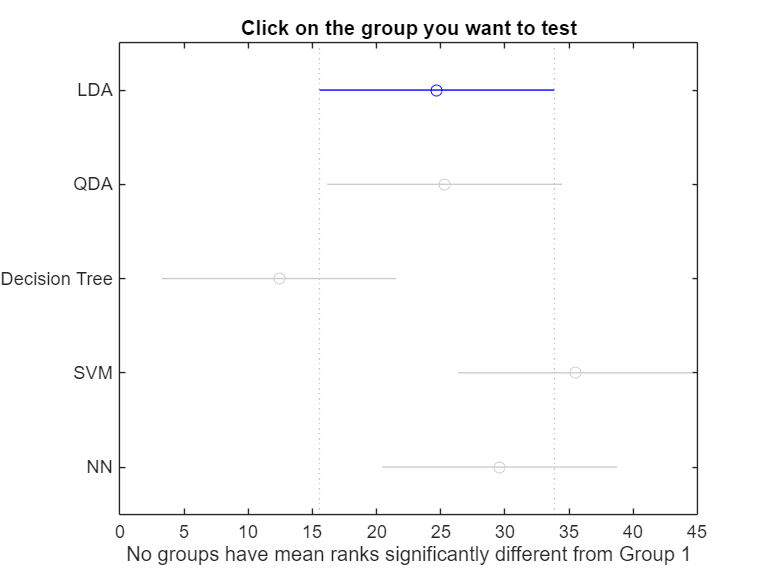

    Grupo1    Grupo2    Lower_CI    Diff     Upper_CI     PValue  
    ______    ______    ________    _____    ________    _________

      1         2       -18.895      -0.6     17.695             1
      1         3       -5.9952      12.3     30.595       0.59135
      1         4       -29.095     -10.8     7.4952       0.97511
      1         5       -23.195      -4.9     13.395             1
      2         3       -5.3952      12.9     31.195       0.47788
      2         4       -28.495     -10.2     8.0952             1
      2         5       -22.595      -4.3     13.995             1
      3         4       -41.395     -23.1    -4.8048     0.0039376
      3         5       -35.495     -17.2     1.0952      0.083153
      4         5       -12.395       5.9     24.195      

% === CARGAR MEJOR MODELO Y PREPARAR COMPARACIÓN ===

%load('modeloFinal_NN_QSAR.mat');

% Extraer sus métricas por fold
f1score_bestNN = metricsFoldsNN.F1Score(:, idx_sencillo, rep);

% Lista de métricas a evaluar
metricNames = {'Accuracy', 'Recall', 'Specificity', 'Precision', 'F1Score'};

% Encontrar índice del modelo más sencillo (5 neuronas, trainscg)
idx_sencillo = find(combinaciones(:,1) == 5 & combinaciones(:,2) == 1);

for m = 1:numel(metricNames)
    metricName = metricNames{m};

    % Extraer valores de cada modelo clásico
    lda_values    = metricsLDA.(metricName);
    qda_values    = qdametrics.(metricName);
    arbol_values  = metricsArbol.(metricName)(:,1);  % Árbol sencillo
    svm_values    = metricsSVM_R1_M1.(metricName);
    nn_values     = metricsFoldsNN.(metricName)(:, idx_sencillo, rep);

    % Concatenar todas las métricas
    combined_values = [lda_values; qda_values; arbol_values; svm_values; nn_values];

    % Crear etiquetas de grupo (1 = LDA, 2 = QDA, 3 = Árbol, 4 = SVM, 5 = NN sencillo)
    numFolds = size(lda_values,1);
    group_labels = [ones(numFolds,1);
                    2*ones(numFolds,1);
                    3*ones(numFolds,1);
                    4*ones(numFolds,1);
                    5*ones(numFolds,1)];

    % Kruskal-Wallis
    [p,~,stats] = kruskalwallis(combined_values, group_labels, 'off');

    % Mostrar resultado
    fprintf('\nTest de Kruskal-Wallis para %s\n', metricName);
    fprintf('P-valor: %.4f\n', p);

    % Si hay diferencias significativas → comparaciones múltiples
    if p < 0.05
        fprintf('Se encontraron diferencias significativas entre los modelos. Realizando comparaciones múltiples...\n');
        
        figure;
        title(sprintf('Comparaciones múltiples para %s', metricName));
        [c,~,~,gnames] = multcompare(stats, 'CType', 'bonferroni');
        
        % Ajustar etiquetas manualmente (OJO: multcompare invierte el orden)
        ax = gca;
        ax.YTickLabel = {'NN', 'SVM', 'Decision Tree', 'QDA', 'LDA'};

        % Mostrar tabla de comparaciones múltiples
        disp(array2table(c, 'VariableNames', {'Grupo1', 'Grupo2', 'Lower_CI', 'Diff', 'Upper_CI', 'PValue'}));
    else
        fprintf('No se encontraron diferencias significativas entre los modelos para %s.\n', metricName);
    end
end

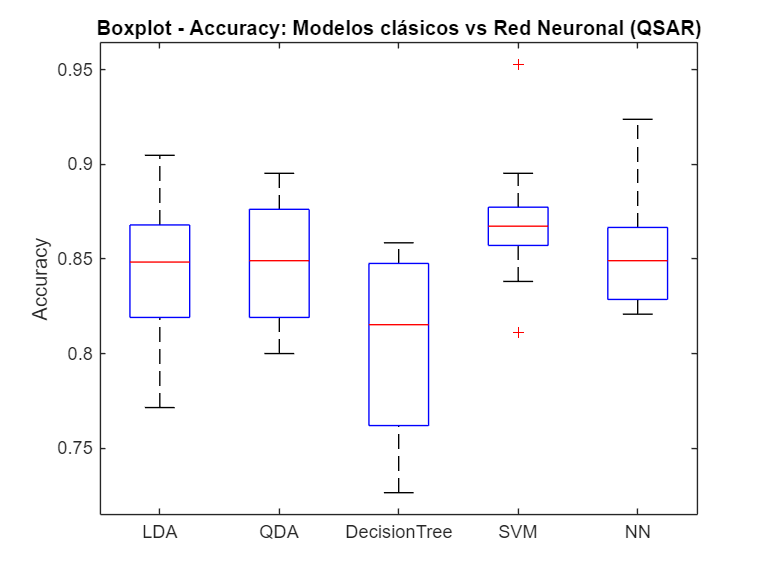

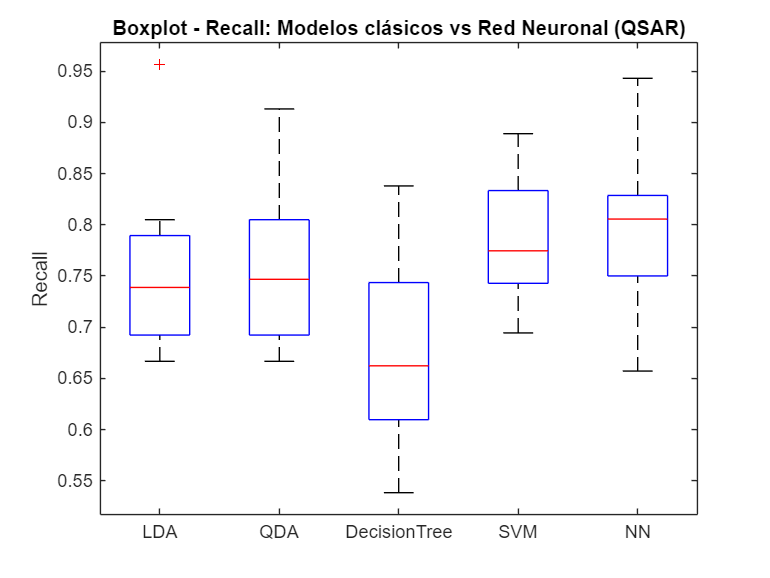

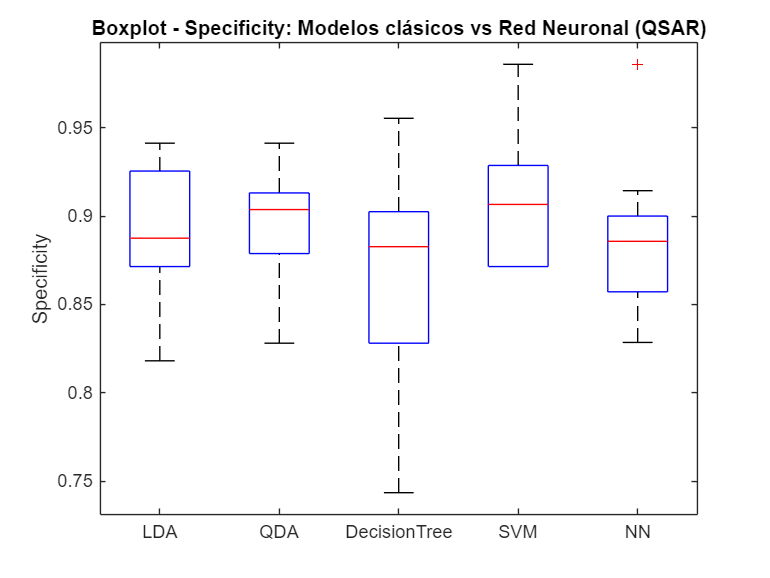

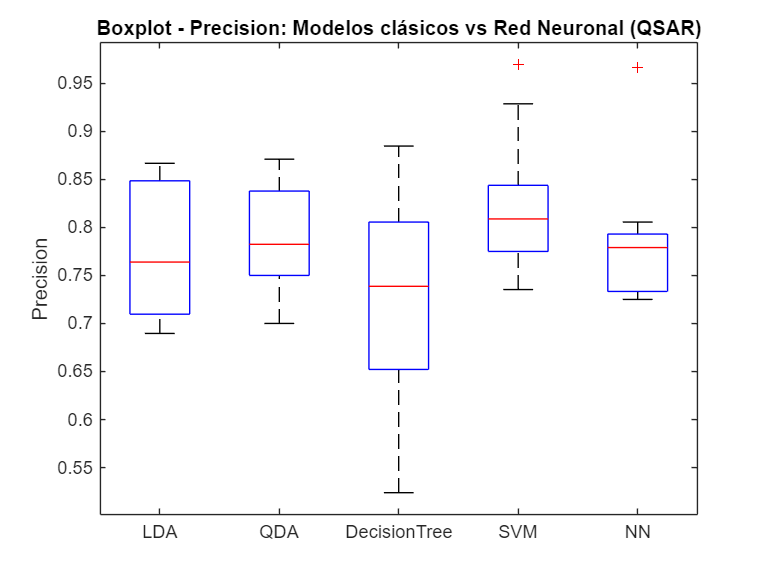

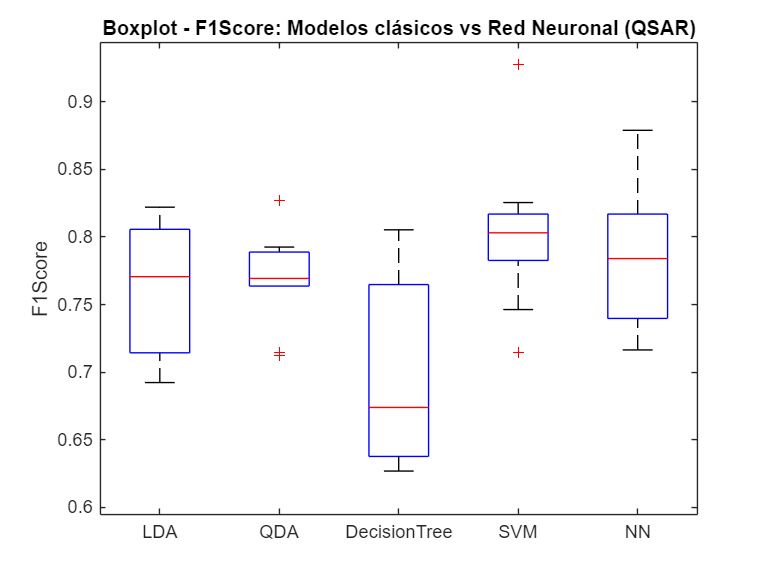

% === BOXPLOT + TABLA RESUMEN MEDIA ± SD ===

% Lista de métricas a evaluar
metricNames = {'Accuracy', 'Recall', 'Specificity', 'Precision', 'F1Score'};
modelNames = {'LDA', 'QDA', 'DecisionTree', 'SVM', 'NN'};
numModels = numel(modelNames);

% Encontrar índice del modelo más sencillo (5 neuronas, trainscg)
idx_sencillo = find(combinaciones(:,1) == 5 & combinaciones(:,2) == 1);

% Inicializar tabla combinada (como cell array para incluir strings formateados)
summaryTable = cell(numModels, numel(metricNames));
summaryTable = cell2table(summaryTable, 'VariableNames', metricNames, 'RowNames', modelNames);

for m = 1:numel(metricNames)
    metricName = metricNames{m};

    % Extraer valores por modelo
    lda_values    = metricsLDA.(metricName);
    qda_values    = qdametrics.(metricName);
    arbol_values  = metricsArbol.(metricName)(:,1);
    svm_values    = metricsSVM_R1_M1.(metricName);
    nn_values     = metricsFoldsNN.(metricName)(:, idx_sencillo, rep);

    % Guardar en arrays
    all_values = {lda_values, qda_values, arbol_values, svm_values, nn_values};

    % Calcular y almacenar media ± sd formateado
    for modelIdx = 1:numModels
        vals = all_values{modelIdx};
        media = mean(vals);
        sd = std(vals);
        summaryTable{modelIdx, metricName} = {sprintf('%.4f ± %.4f', media, sd)};
    end

    % Crear etiquetas para boxplot
    numFolds = size(lda_values,1);
    group_labels = [repmat("LDA", numFolds,1);
                    repmat("QDA", numFolds,1);
                    repmat("DecisionTree", numFolds,1);
                    repmat("SVM", numFolds,1);
                    repmat("NN", numFolds,1)];

    % Generar boxplot
    figure;
    boxplot([lda_values; qda_values; arbol_values; svm_values; nn_values], group_labels);
    ylabel(metricName);
    title(sprintf('Boxplot - %s: Modelos clásicos vs Red Neuronal (QSAR)', metricName));
end


% Mostrar tabla resumen final
disp('=== Tabla resumen (media ± sd) por modelo y métrica ===');

=== Tabla resumen (media ± sd) por modelo y métrica ===


disp(summaryTable);

                         Accuracy                Recall               Specificity             Precision               F1Score      
                    ___________________    ___________________    ___________________    ___________________    ___________________

    LDA             {'0.8417 ± 0.0382'}    {'0.7573 ± 0.0841'}    {'0.8880 ± 0.0409'}    {'0.7748 ± 0.0705'}    {'0.7620 ± 0.0475'}
    QDA             {'0.8474 ± 0.0307'}    {'0.7543 ± 0.0763'}    {'0.8981 ± 0.0337'}    {'0.7899 ± 0.0586'}    {'0.7678 ± 0.0343'}
    DecisionTree    {'0.8018 ± 0.0495'}    {'0.6811 ± 0.0938'}    {'0.8666 ± 0.0694'}    {'0.7289 ± 0.1130'}    {'0.6957 ± 0.0662'}
    SVM             {'0.8701 ± 0.0371'}    {'0.7861 ± 0.0621'}    {'0.9127 ± 0.0401'}    {'0.8249 ± 0